class1 = 'TURMER';
class2 = 'LUSMEG';

[XTrainBase5,YTrain,fsTrain] = prepareTransformedCell('train',5);

XTrainMfcc5 = cellfun(@(a,b) extractMfcc(a,b),XTrainBase5,fsTrain,'UniformOutput',false);

[XTrain1,YTrain1,XVal,YVal] = createValidationSplit(XTrainMfcc5,YTrain,"Split",0.05);

[XTestBase5,YTest,fsTest] = prepareTransformedCell('test',5);
XTestMfcc5 = cellfun(@(a,b) extractMfcc(a,b),XTestBase5,fsTest,'UniformOutput',false);

numObservations = numel(XTrain1);
for i=1:numObservations
    sequence = XTrain1{i};
    sequenceLengths(i) = size(sequence,2);
end
[sequenceLengths,idx] = sort(sequenceLengths);
XTrainMfcc = XTrain1(idx);
YTrain = YTrain(idx);

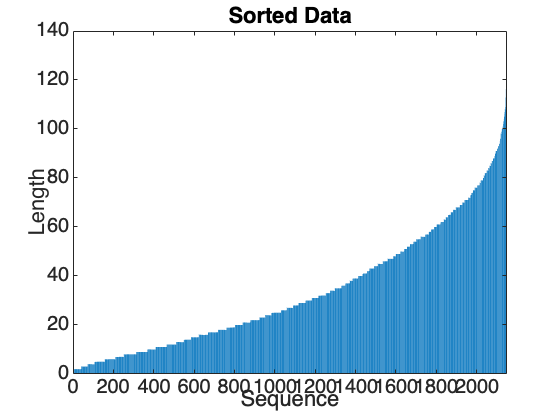

bar(sequenceLengths)
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")

numObservationsTest = numel(XTestMfcc5);
for i=1:numObservationsTest
    sequence = XTestMfcc5{i};
    sequenceLengthsTest(i) = size(sequence,2);
end

[sequenceLengthsTest,idx] = sort(sequenceLengthsTest);
XTestMfcc = XTestMfcc5(idx);
YTest = YTest(idx);

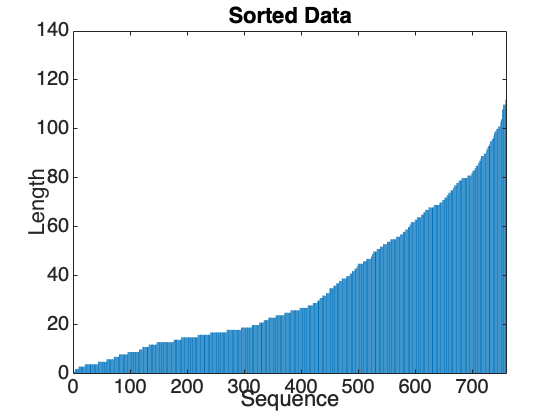

bar(sequenceLengthsTest)
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")

rnnVEvalCell = {};

## Model 1

miniBatchSize = 100;
inputSize = 39;
numHiddenUnits = 100;
numClasses = 2;

layers1 = [
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits,OutputMode="last")
    dropoutLayer(0.2)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

maxEpochs = 100;
options1 = trainingOptions("adam", ...
    "MiniBatchSize",miniBatchSize, ...
    "GradientThreshold",1, ...
    "Plots","training-progress", ...
    "SequenceLength","longest", ...
    "Shuffle","never", ...
    "MaxEpochs",maxEpochs, ...
    "ValidationData",{XVal,YVal}, ...
    "Verbose",0);

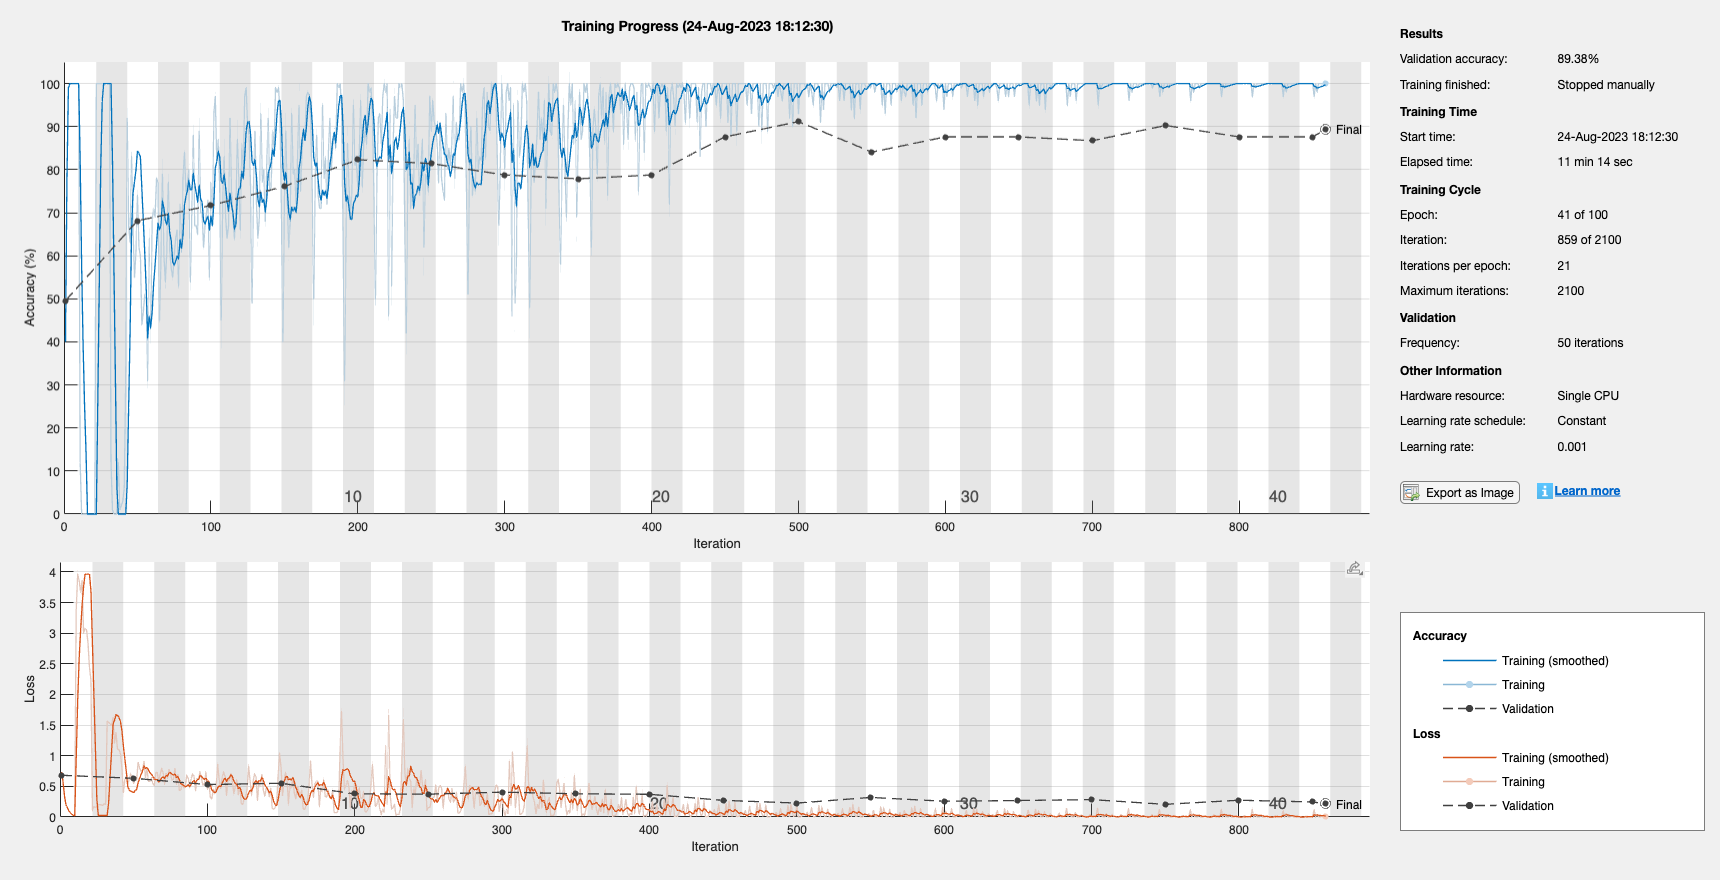

rnnV1 = trainNetwork(XTrain1,YTrain1,layers1,options1);

Stopped manually after 41 epochs

16s per epoch

eval1 = generateEvaluationCell(rnnV1,1,XTestMfcc,YTest,class1,miniBatchSize);
rnnVEvalCell = [rnnVEvalCell;eval1];

## Model 2

miniBatchSize = 100;
inputSize = 39;
numHiddenUnits = 100;
numClasses = 2;
filterSize = 3;
numFilters = 32;

layers2 = [
    sequenceInputLayer(inputSize)
    convolution1dLayer(filterSize,numFilters,Padding="causal")
    layerNormalizationLayer
    reluLayer
    dropoutLayer(0.2)
    convolution1dLayer(filterSize,2*numFilters,Padding="causal")
    layerNormalizationLayer
    reluLayer
    globalAveragePooling1dLayer
    bilstmLayer(numHiddenUnits,OutputMode="last")
    dropoutLayer(0.5)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

maxEpochs = 100;
options2 = trainingOptions("adam", ...
    "MiniBatchSize",miniBatchSize, ...
    "GradientThreshold",1, ...
    "Plots","training-progress", ...
    "SequenceLength","longest", ...
    "Shuffle","never", ...
    "MaxEpochs",maxEpochs, ...
    "ValidationData",{XVal,YVal}, ...
    "Verbose",0);

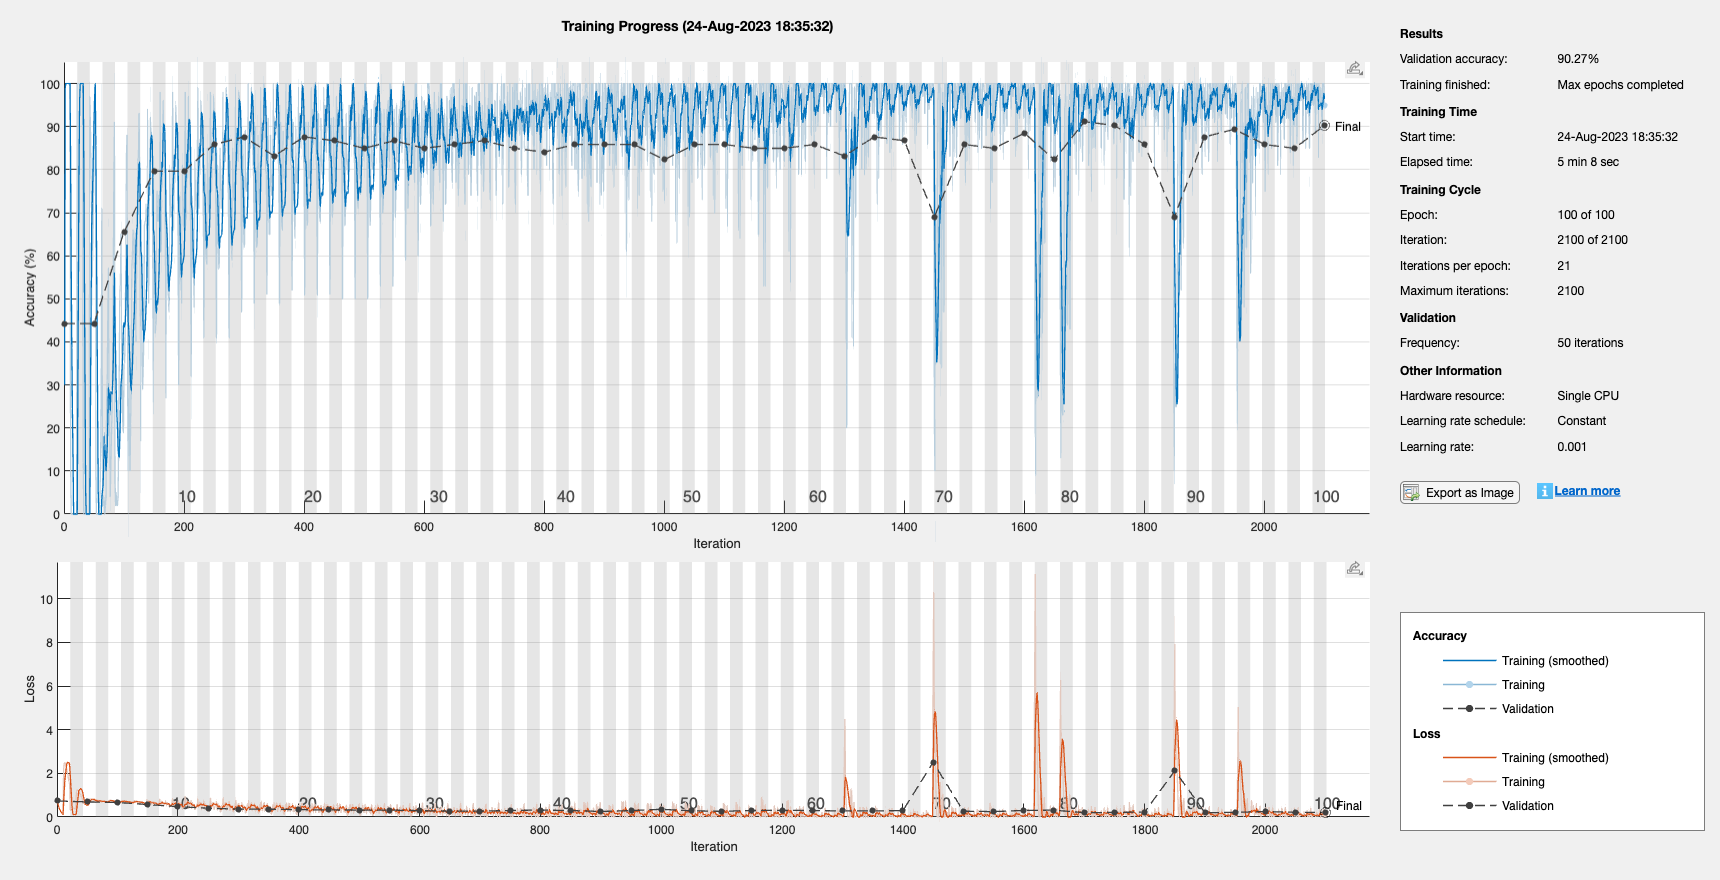

rnnV2 = trainNetwork(XTrain1,YTrain1,layers2,options2);

Training completed

3s per epoch

eval2 = generateEvaluationCell(rnnV2,2,XTestMfcc,YTest,class1,miniBatchSize);
rnnVEvalCell = [rnnVEvalCell;eval2];

## Model 2

miniBatchSize = 100;
inputSize = 39;
numHiddenUnits = 100;
numClasses = 2;
filterSize = 3;
numFilters = 32;

layers3 = [
    sequenceInputLayer(inputSize)
    convolution1dLayer(filterSize,numFilters,Padding="causal")
    layerNormalizationLayer
    reluLayer
    dropoutLayer(0.2)
    convolution1dLayer(filterSize,2*numFilters,Padding="causal")
    layerNormalizationLayer
    reluLayer
    dropoutLayer(0.2)
    globalAveragePooling1dLayer
    gruLayer(numHiddenUnits,OutputMode="last")
    dropoutLayer(0.5)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

maxEpochs = 100;
options3 = trainingOptions("adam", ...
    "MiniBatchSize",miniBatchSize, ...
    "GradientThreshold",1, ...
    "Plots","training-progress", ...
    "SequenceLength","longest", ...
    "Shuffle","never", ...
    "MaxEpochs",maxEpochs, ...
    "ValidationData",{XVal,YVal}, ...
    "Verbose",0);

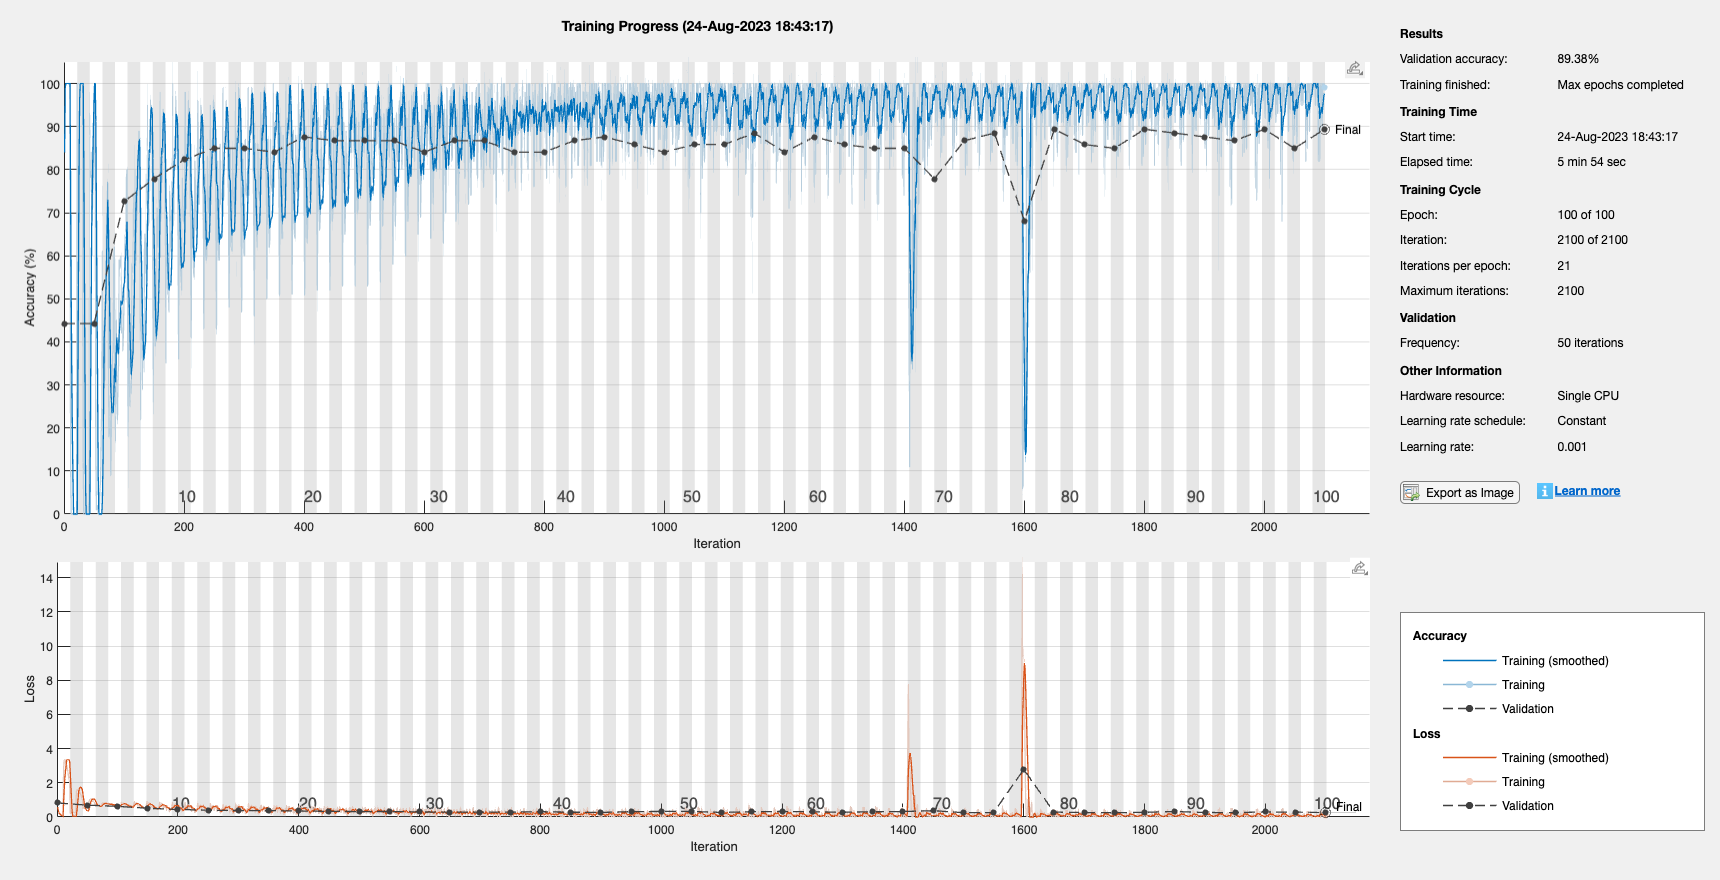

rnnV3 = trainNetwork(XTrain1,YTrain1,layers3,options3);

Training completed

3s per epoch

eval3 = generateEvaluationCell(rnnV3,3,XTestMfcc,YTest,class1,miniBatchSize);
rnnVEvalCell = [rnnVEvalCell;eval3];

rnnMfccEvalData = zeros(3,2);
for i = 1:3
    rnnMfccEvalData(i,1) = rnnVEvalCell{i,2};
    rnnMfccEvalData(i,2) = rnnVEvalCell{i,3};
end

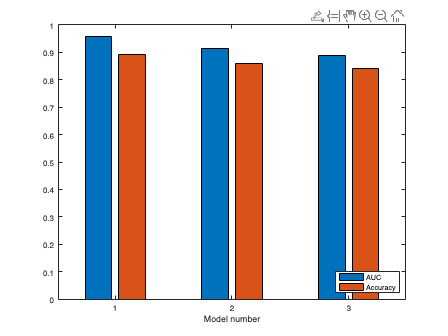

figure;
bar(1:3,rnnMfccEvalData)
ylim([0 1])
legend({'AUC','Accuracy'},"Location","southeast")
xlabel('Model number')

function newSyllable = transformSyllable(syllable,fs,lengthMS)
lengthSamples = fs*lengthMS/1000;
syllable = mono(syllable);
newSyllable = syllable(:);
count = 1;
while length(newSyllable) < lengthSamples
    newSyllable = [newSyllable;newSyllable];
    if count > 1000
        fprintf('breaking');
        length(newSyllable)
        break;
    end
end
newSyllable = newSyllable(1:lengthSamples);
end

function mfccFeature = extractMfcc(signal,fs)
if length(signal) < round(fs*0.03)
    signal = [signal;zeros(round(fs*0.03)-length(signal),1)];
end
[coeffs, delta, ddelta, ~] = mfcc(signal,fs,"LogEnergy","ignore");
mfccFeature = [coeffs,delta,ddelta]';
end

function evalCell = generateEvaluationCell(model,archNumber,XTest,YTest,posClass,miniBatchSize)
[auc,accuracy,ROCX,ROCY] = evaluateRNN(model,XTest,YTest,posClass,miniBatchSize);
evalCell = {archNumber,auc,accuracy,ROCX,ROCY};
end

function [X,Y,fs] = prepareTransformedCell(type,numConcatSyllables,class1,class2,maxSize,syllLengthMs)
arguments
type
numConcatSyllables = 5
class1 = 'TURMER'
class2 = 'LUSMEG'
maxSize = 1.5*44100
syllLengthMs = 80
end
[class1Samples,class1Fs] = retrieveSamples(class1,type,'MaxSamplesPerBird',40,'NumConcatSyllables',numConcatSyllables);
[class2Samples,class2Fs] = retrieveSamples(class2,type,'MaxSamplesPerBird',40,'NumConcatSyllables',numConcatSyllables);
allSamples = vertcat(class1Samples,class2Samples);
allFs = vertcat(class1Fs,class2Fs);

labels = ones(length(allSamples),1);
labels(1:length(class1Samples)) = -1;
labels = categorical(labels,[-1 1],{'TURMER','LUSMEG'});

validIdx = find(cellfun('size',allSamples,1)<maxSize);
allSamples = allSamples(validIdx);

Y = labels(validIdx);
fs = allFs(validIdx);

X = allSamples;
% X = cellfun(@(a,b) transformSyllable(a,b,syllLengthMs),allSamples,fs,'UniformOutput',false);
end